## Time Scaling

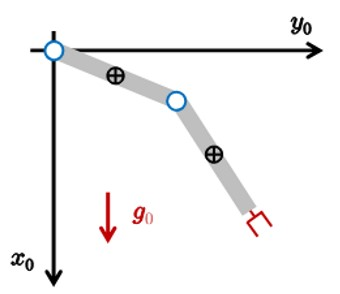

syms q1 q2 dq1 dq2 m1 m2 l1 l2 I1 I2 g0 positive
syms d1 d2 l positive

% Joint 1
x1 = d1*cos(q1);
y1 = d1*sin(q1);

vx1 = diff(x1, q1)*dq1 + diff(x1, q2)*dq2;
vy1 = diff(y1, q1)*dq1 + diff(y1, q2)*dq2;

T1_tr = 0.5*m1*[vx1 vy1]*[vx1; vy1;];
T1_rot = 0.5*I1*dq1^2;

T1 = T1_tr+T1_rot

$$T1 = \frac{m_{1}\,{d_{1}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{m_{1}\,{d_{1}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{2}+\frac{I_{1}\,{{\mathrm{dq}}_{1}}^{2}}{2}$$


% Joint 2
x2 = l1*cos(q1)+d2*cos(q1+q2);
y2 = l1*sin(q1)+d2*sin(q1+q2);

vx2 = diff(x2, q1)*dq1 + diff(x2, q2)*dq2

$$vx2 = -{\mathrm{dq}}_{1}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-d_{2}\,{\mathrm{dq}}_{2}\,\sin\left(q_{1}+q_{2}\right)$$

vy2 = diff(y2, q1)*dq1 + diff(y2, q2)*dq2

$$vy2 = {\mathrm{dq}}_{1}\,\left(d_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+d_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{1}+q_{2}\right)$$


T2_tr = 0.5*m1*[vx1 vy1]*[vx1; vy1;];
T2_rot = 0.5*I2*[0 0 dq1+dq2]*[0; 0; dq1+dq2;];

T2 = T2_tr+T2_rot

$$T2 = \frac{I_{2}\,{\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}^{2}}{2}+\frac{{d_{1}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,m_{1}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{{d_{1}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\right)}^{2}}{2}$$


T = T1+T2

$$T = \frac{I_{2}\,{\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}^{2}}{2}+\frac{I_{1}\,{{\mathrm{dq}}_{1}}^{2}}{2}+{d_{1}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,m_{1}\,{\cos\left(q_{1}\right)}^{2}+{d_{1}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\right)}^{2}$$


% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);

M = [M11, M12;
     M21, M22;];

M = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\left(\begin{array}{cc} 2\,m_{1}\,{d_{1}}^{2}+I_{1}+I_{2} & I_{2}\\ I_{2} & I_{2} \end{array}\right)$$


% Potential Energy and Gravity Terms
U1 = m1*g0*((l/2)*cos(q1));
U2 = m1*g0*((l/2)*cos(q1)+((3/2)*l)*cos(q1+q2));
U = [U1+U2;];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100)

$$g\_q = \left(\begin{array}{c} -\frac{g_{0}\,l\,m_{1}\,\left(3\,\sin\left(q_{1}+q_{2}\right)+2\,\sin\left(q_{1}\right)\right)}{2}\\ -\frac{3\,g_{0}\,l\,m_{1}\,\sin\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$


% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(2,2));

% using the Christoffel symbols for a 3-DOF system
q  = [q1; q2;];
dq = [dq1; dq2;];

% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(2,2));

% Formula dei coefficienti di Christoffel (Robotics):
%   C(i,j) = 1/2 * SUM_k [ dM(i,j)/dq_k + dM(i,k)/dq_j - dM(k,j)/dq_i ] * dq_k
% Poi il vettore c(q,dq) = C(q,dq) * dq
for i = 1:2
    for j = 1:2
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

% Finalmente calcolo il vettore c(q, dq):
c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$


disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

### Find K

%% ------------------------------------------------------------
%  Data from the problem statement
%% ------------------------------------------------------------
tau1_t1  = 140.0;     % [Nm]  (total torque at joint 1, time t1)
tau2_t2  = 25.0;      % [Nm]  (total torque at joint 2, time t2)

g1_t1    = 34.6836;   % [Nm]  (gravity torque at q(t1))
g2_t2    = 12.2625;   % [Nm]  (gravity torque at q(t2))

tauMax1  = 100;       % [Nm]  (max allowable torque at joint 1)
tauMax2  = 20;        % [Nm]  (max allowable torque at joint 2)

T        = 3.0;       % [s]   (original motion duration)

%% ------------------------------------------------------------
%  Compute individual scaling factors for each joint
%
%  In the standard “1/k²” scaling law, the gravity part g_i(q)
%  does not scale, but the excess (tau_i - g_i) does.  For each
%  joint i, the condition
%     (tau_i - g_i)/k^2 + g_i  <= tauMax_i
%  can be rearranged to solve for k.
% -------------------------------------------------------------
%
%  JOINT 1:
%     (tau1(t1) - g1(t1))/k^2 + g1(t1) <= tauMax1
%   => (tau1(t1) - g1(t1))/k^2 <= tauMax1 - g1(t1)
%   =>  1/k^2 <= (tauMax1 - g1(t1)) / (tau1(t1) - g1(t1))
%   =>   k^2 >= (tau1(t1) - g1(t1)) / (tauMax1 - g1(t1))
%   =>   k   >= sqrt( ... )
%
dynPart_1 = tau1_t1 - g1_t1;     % "dynamic" portion
margin_1  = tauMax1 - g1_t1;     % how much torque room is left above gravity
k1 = sqrt( dynPart_1 / margin_1 );

%  JOINT 2:
%     (tau2(t2) - g2(t2))/k^2 + g2(t2) <= tauMax2
%  => same algebraic form, so again k >= sqrt(...)
dynPart_2 = tau2_t2 - g2_t2;
margin_2  = tauMax2 - g2_t2;
k2 = sqrt( dynPart_2 / margin_2 );

% The overall k must satisfy *both* joints' requirements
k = max(k1, k2);

% The new, longer motion time
T_prime = k * T;

%  Compute the new scaled torques at time instants t1' and t2'
%
%    tau_i'(t_i') = ( [tau_i(t_i)] - g_i )/k^2   +   g_i
tau1_scaled_t1 = (tau1_t1 - g1_t1)/k^2 + g1_t1;
tau2_scaled_t2 = (tau2_t2 - g2_t2)/k^2 + g2_t2;

fprintf('k1 = %.4f\n', k1);

k1 = 1.2698


fprintf('k2 = %.4f\n', k2);

k2 = 1.2830


fprintf('Overall time-scaling factor k = %.4f\n', k);

Overall time-scaling factor k = 1.2830


fprintf('New motion duration T'' = %.4f s\n\n', T_prime);

New motion duration T' = 3.8491 s




fprintf('Scaled torque at joint 1, t1'' = %.4f Nm\n', tau1_scaled_t1);

Scaled torque at joint 1, t1' = 98.6589 Nm


fprintf('Scaled torque at joint 2, t2'' = %.4f Nm\n', tau2_scaled_t2);

Scaled torque at joint 2, t2' = 20.0000 Nm
